# Fuel Economy - Stepwise Linear Regression

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

carData = readtable("./data/carEcon.xlsx", Sheet="carData");
carTest = readtable("./data/carEcon.xlsx", Sheet="carTest");
carTrain = readtable("./data/carEcon.xlsx", Sheet="carTrain");
whos carData carTrain carTest

  Name            Size             Bytes  Class    Attributes

  carData       600x15            380315  table              
  carTest       192x15            124705  table              
  carTrain      408x15            259725  table              



## Tasks 1 & 3

The table `carData` has been split into a training set, `carTrain`, and a test set, `carTest`. The response variable is `"FuelEcon"`.

Use the `"Lower"` or `"Upper"` properties with a model specification value to restrict a model to a specific set of terms.

`lnMdl` `=` `stepwiselm``(``table``,``...`

    `"Upper"``,``"``modelspec``"``)`

mdl = stepwiselm(carTrain, "Upper", "linear", "Criterion", "aic");

1. Adding City_Highway, AIC = 1971.4141
2. Adding EngDisp, AIC = 1553.971
3. Adding Drive, AIC = 1509.3114
4. Adding AC, AIC = 1492.5684
5. Adding Valves_Cyl, AIC = 1480.9467
6. Adding Car_Truck, AIC = 1460.7694
7. Adding Transmission, AIC = 1445.2142
8. Adding FuelType, AIC = 1438.4168
9. Adding Comp, AIC = 1427.3392
10. Adding RatedHP, AIC = 1419.1864
11. Adding Weight, AIC = 1414.2129
12. Adding PRP, AIC = 1410.1779
13. Removing EngDisp, AIC = 1410.2


econPred = predict(mdl, carTest);

## Task 2

RMSE = mdl.RMSE

RMSE = 1.3195

Compare predicted and actual responses.

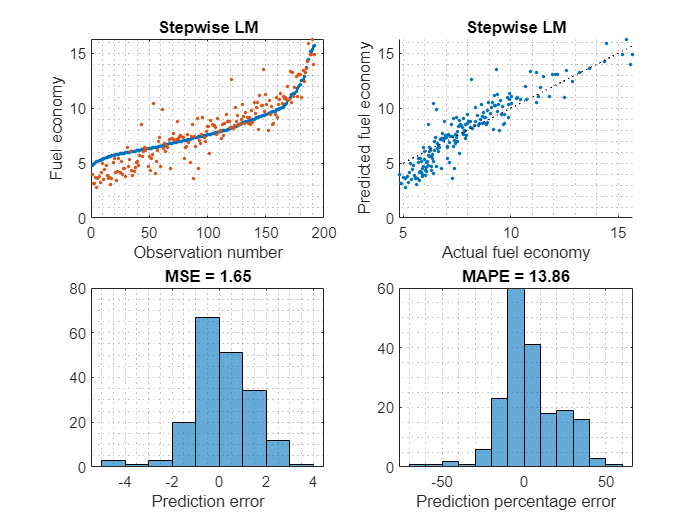

evaluateFit(carTest.FuelEcon, econPred, "Stepwise LM")

function evaluateFit(y, ypred, name)
    figure
    % Plot against observation number
    subplot(2,2,1)
    plot(y,'.')
    grid minor
    hold on
    plot(ypred,'.')
    hold off
    title(name)
    xlabel('Observation number')
    ylabel('Fuel economy')
    
    % Plot predicted and actual against each other
    subplot(2,2,2)
    scatter(y,ypred,'.')
    grid minor
    % Add 45-degree line
    xl = xlim;
    hold on
    plot(xl,xl,'k:')
    hold off
    title(name)
    xlabel('Actual fuel economy')
    ylabel('Predicted fuel economy')
    
    % Distribution of errors
    subplot(2,2,3)
    err = y-ypred;
    MSE = mean(err.^2,'omitnan');
    histogram(err)
    grid minor    
    title(['MSE = ',num2str(MSE,4)])
    xlabel('Prediction error')
    
    % Distribution of percentage errors
    subplot(2,2,4)
    err = 100*err./y;
    MAPE = mean(abs(err),'omitnan');
    histogram(err)
    grid minor
    title(['MAPE = ',num2str(MAPE,4)])
    xlabel('Prediction percentage error')
end